# Second-level Stats (Mixed-effects)

*Please contact Ted (huppert1@pitt.edu) or Hendrik (hes73@pitt.edu) to request more demos, suggestions, feedback, etc. We will update this script as needed. *

## 4.1 Task-based

This example show how to run the second level stats (mixed effect). Mixed effect can handle continuous, categorical, and ordinal variables. 

clear all
clc

load  AnalyzIR_Dataset1.mat

demo = readtable('/Users/hendriksantosa/Library/CloudStorage/OneDrive-UniversityofPittsburgh/NIRS_Summer_Course/Presentations/Day2/TableDemographics.xlsx', 'Format', 'auto');

job=nirs.modules.AddDemographics;
job.allowMissing = true;
job.demoTable=demo;
job.varToMatch='subject';
raw=job.run(raw);

% Basic Pipelines
job = nirs.modules.RenameStims();
job.listOfChanges = {'A',  'TaskA'; 'B', 'TaskB'};
job = nirs.modules.OpticalDensity(job);
job = nirs.modules.Resample(job);
job.Fs = 1; %for speed
job = nirs.modules.BeerLambertLaw(job);
Hb = job.run(raw);

% First Level
job = nirs.modules.GLM();
Stats=job.run(Hb);

......................................................................Finished    1 of   68.
......................................................................Finished    2 of   68.
......................................................................Finished    3 of   68.
......................................................................Finished    4 of   68.
......................................................................Finished    5 of   68.
......................................................................Finished    6 of   68.
......................................................................Finished    7 of   68.
......................................................................Finished    8 of   68.
......................................................................Finished    9 of   68.
......................................................................Finished   10 of   68.
......................................................................

disp('This process takes about 1 min')

This process takes about 1 min


Elapsed time is 68.975026 seconds.


**Continuous Variable**

% Second Level
job=nirs.modules.MixedEffects;
job.formula='beta ~ -1  + cond + cond:ADHD + (1|AgeMonths) + (1|Sex) + (1|HeadSize)'; %continuous
job.robust=true;
job.include_diagnostics = true; %This is need to plot the scatter plot
Group1 = job.run(Stats);  
disp('This process takes about 1 min')

This process takes about 1 min


%Check the final conditions
Group1.conditions

ans = 4×1 cell array
    {'TaskA'     }
    {'TaskA:ADHD'}
    {'TaskB'     }
    {'TaskB:ADHD'}


Elapsed time is 60.128780 seconds.


**Categorical Variable**

job=nirs.modules.MixedEffects;
job.formula='beta ~ -1  + cond:Risk1 + (1|AgeMonths) + (1|Sex) + (1|HeadSize)'; %Categorical
job.robust=true;
Group2 = job.run(Stats); 
disp('This process takes about 1.5 min')

This process takes about 1.5 min


%Check the final conditions
Group2.conditions

ans = 6×1 cell array
    {'TaskA:Risk1_A'}
    {'TaskA:Risk1_B'}
    {'TaskA:Risk1_C'}
    {'TaskB:Risk1_A'}
    {'TaskB:Risk1_B'}
    {'TaskB:Risk1_C'}


Elapsed time is 73.019233 seconds.


**To see the results**

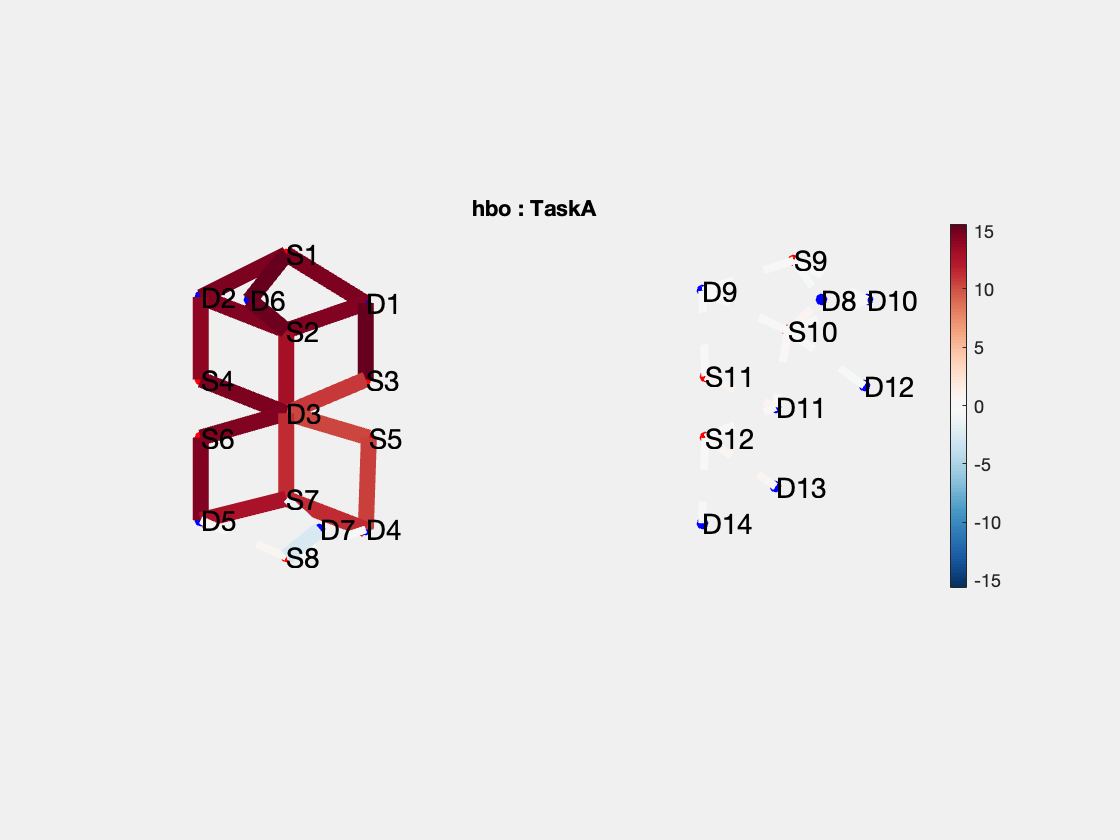

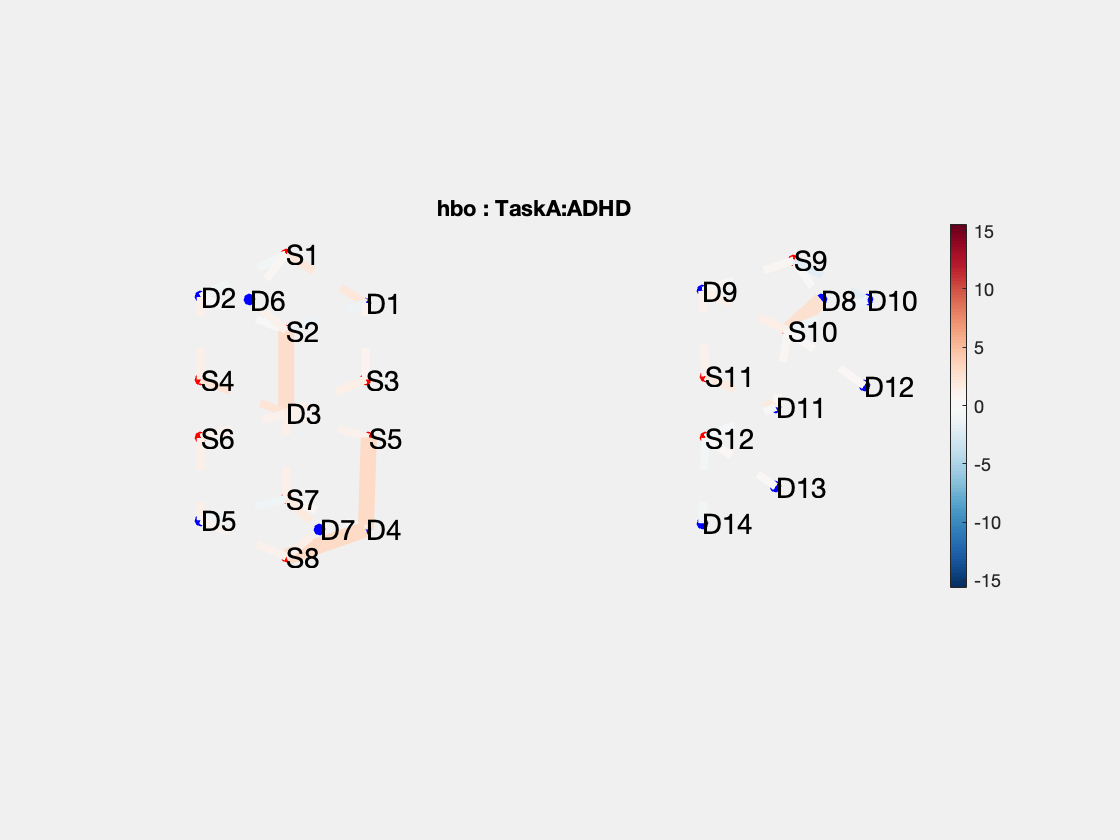

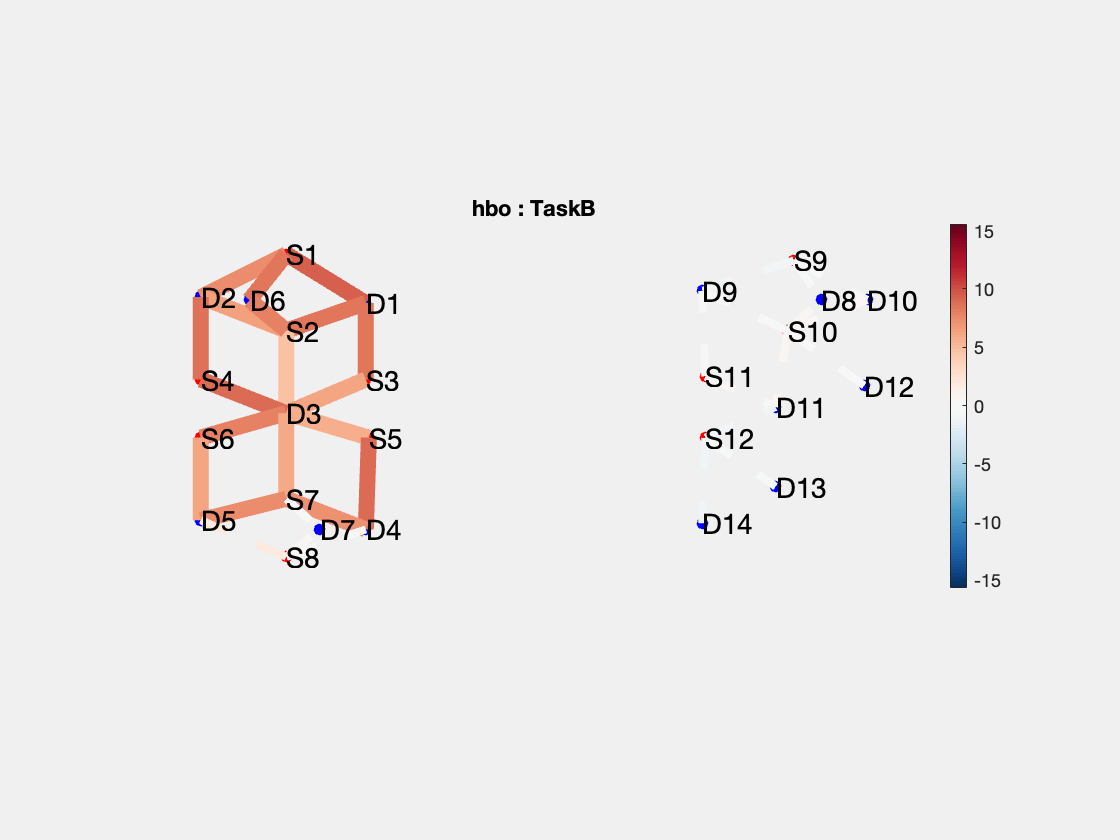

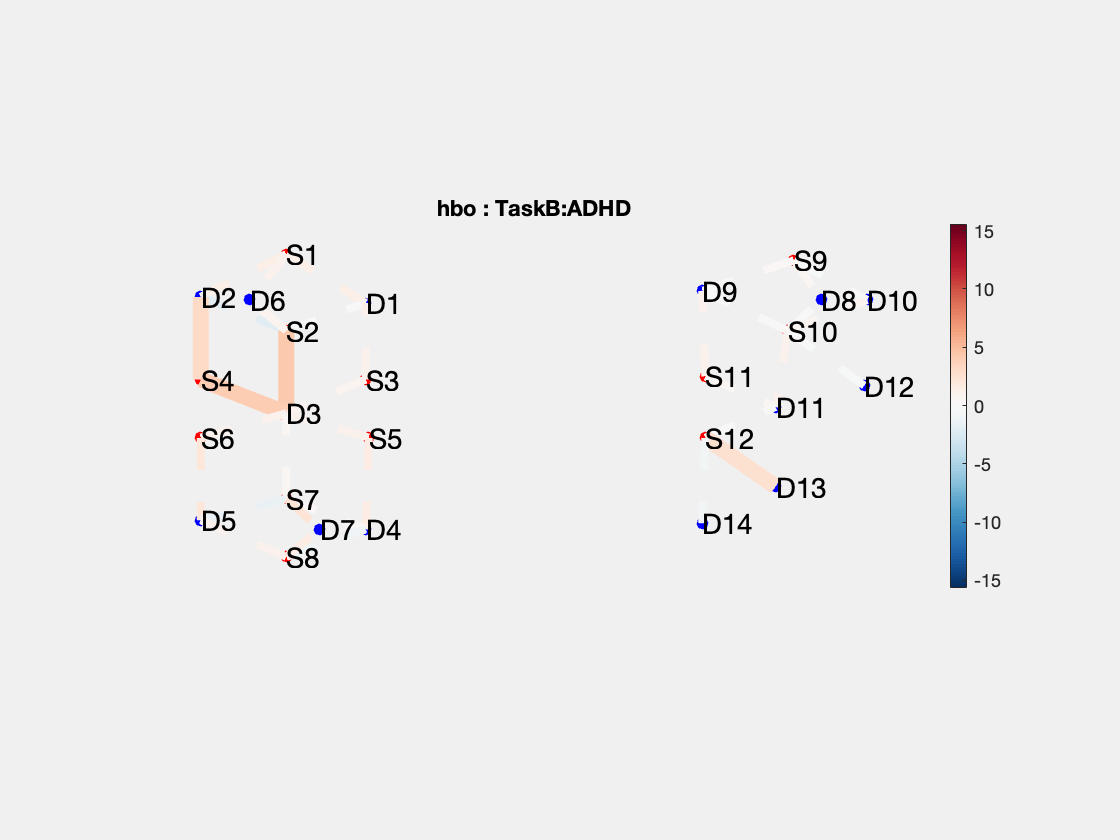

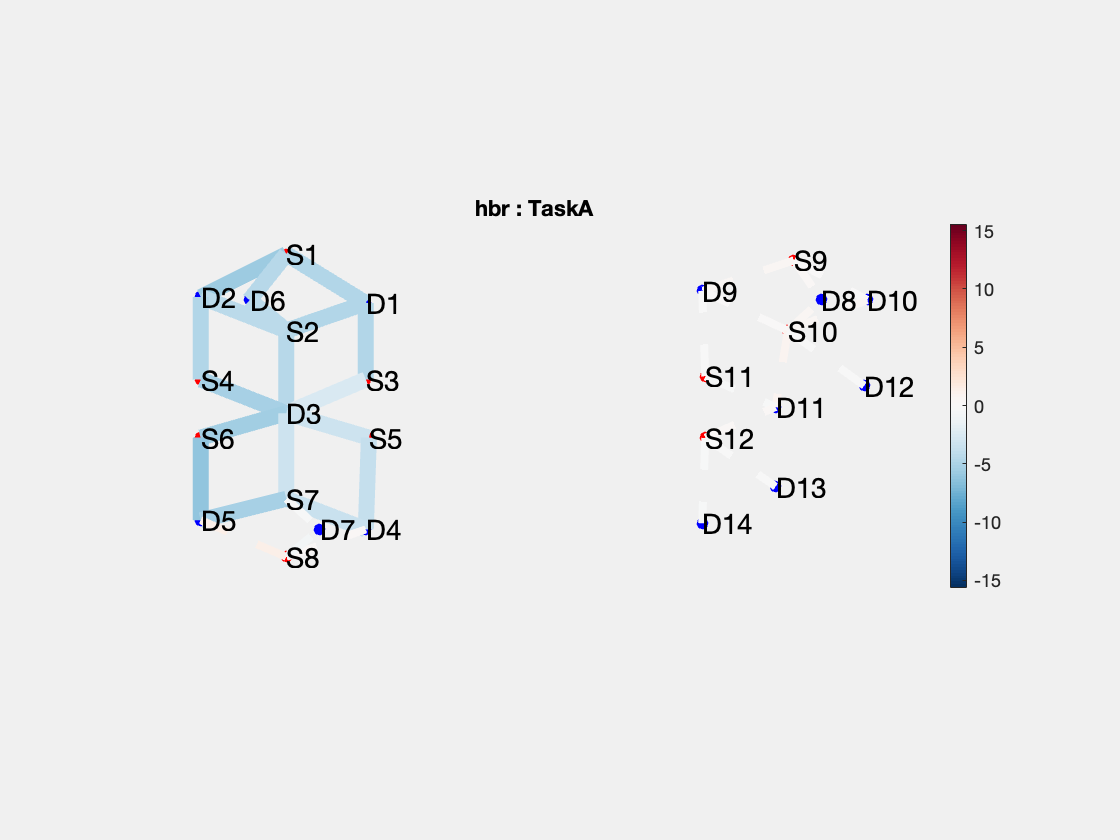

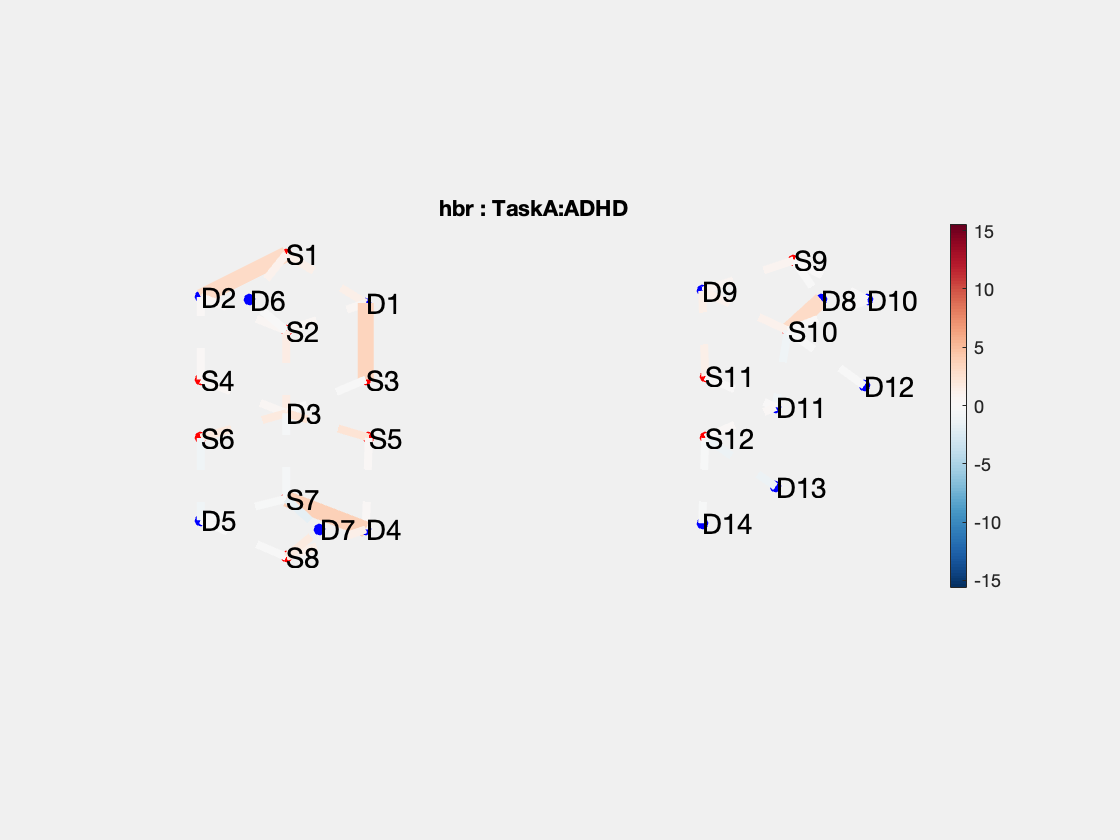

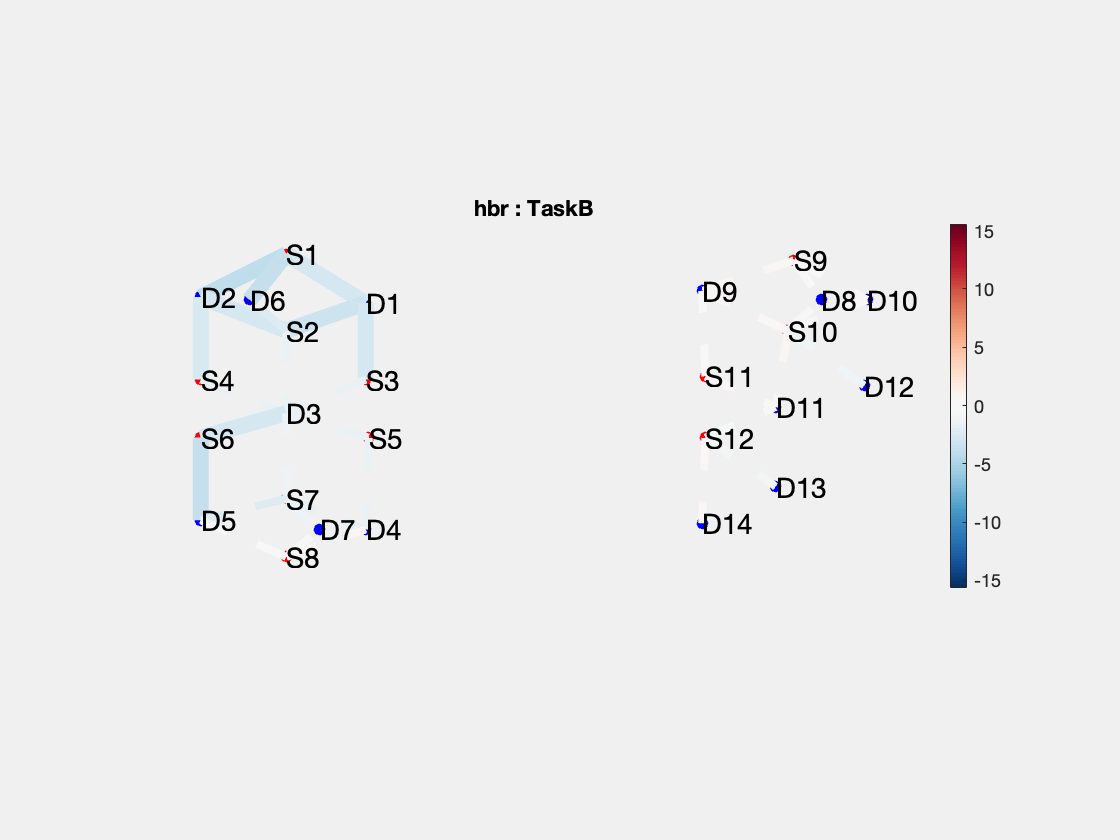

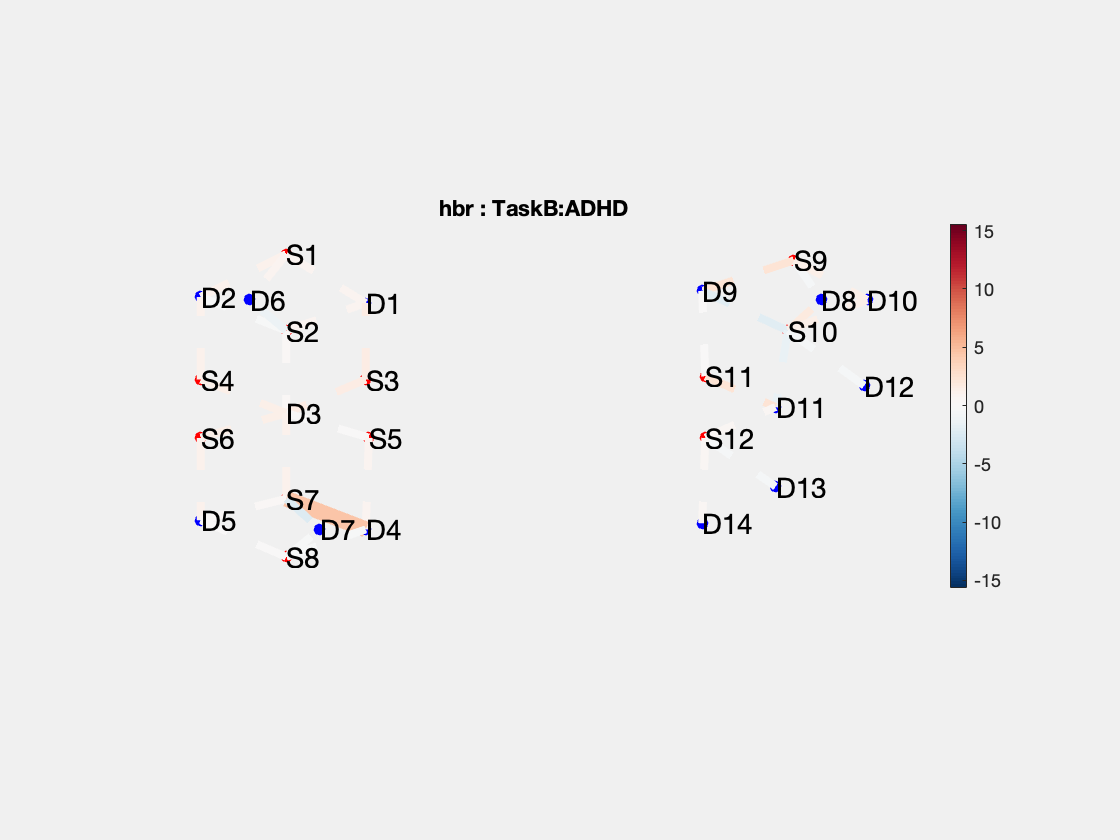

ans =   1×8 Figure array:

    Figure    Figure    Figure    Figure    Figure    Figure    Figure    Figure


% Activation maps
Group1.draw('tstat',[],'q<0.05')

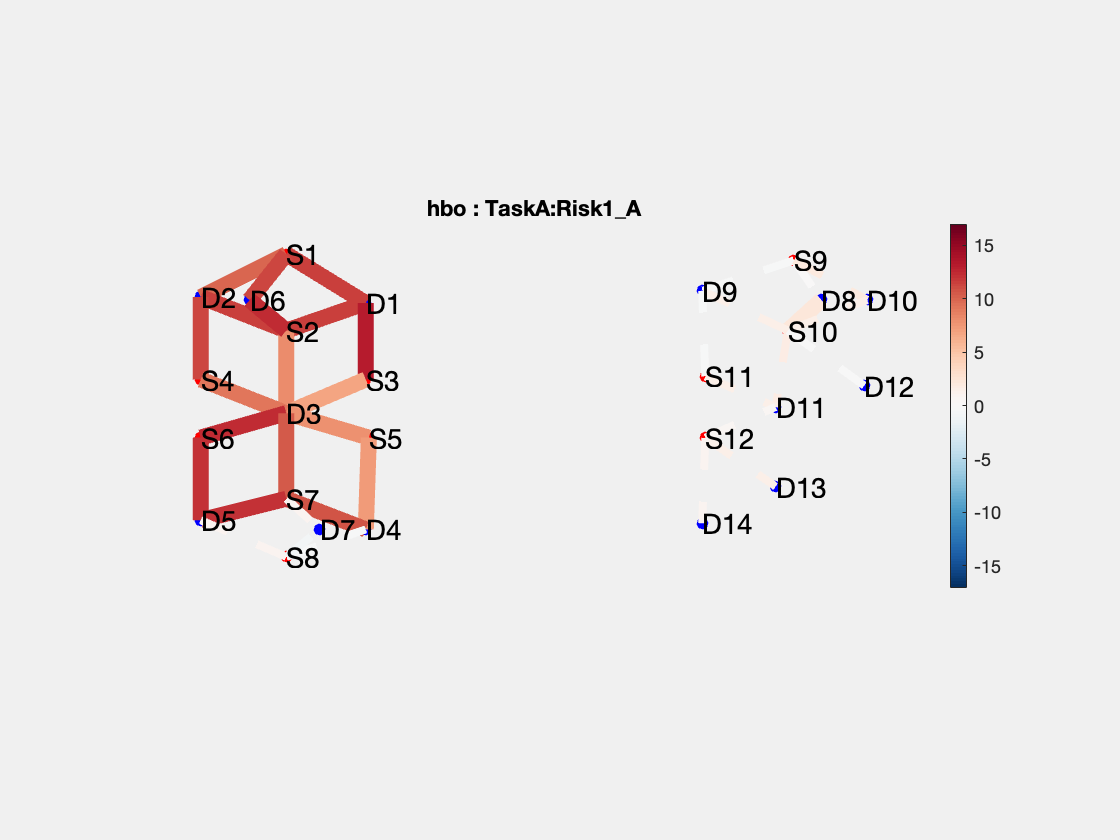

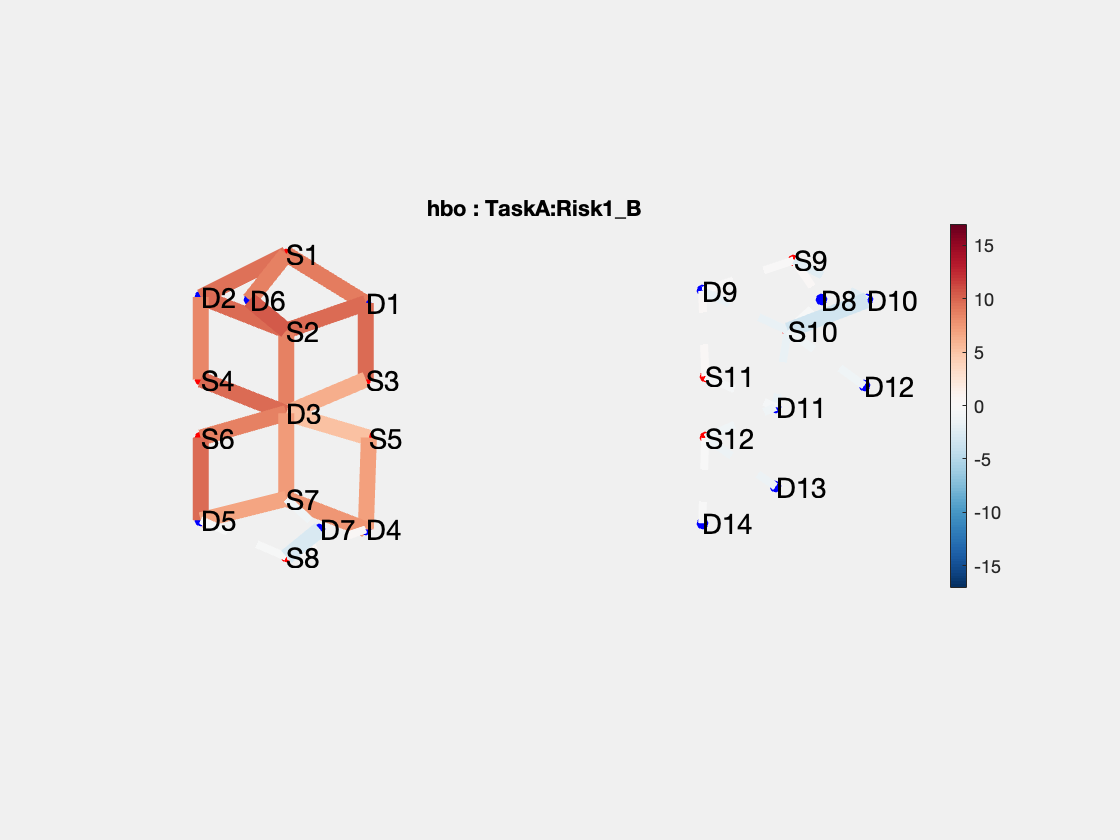

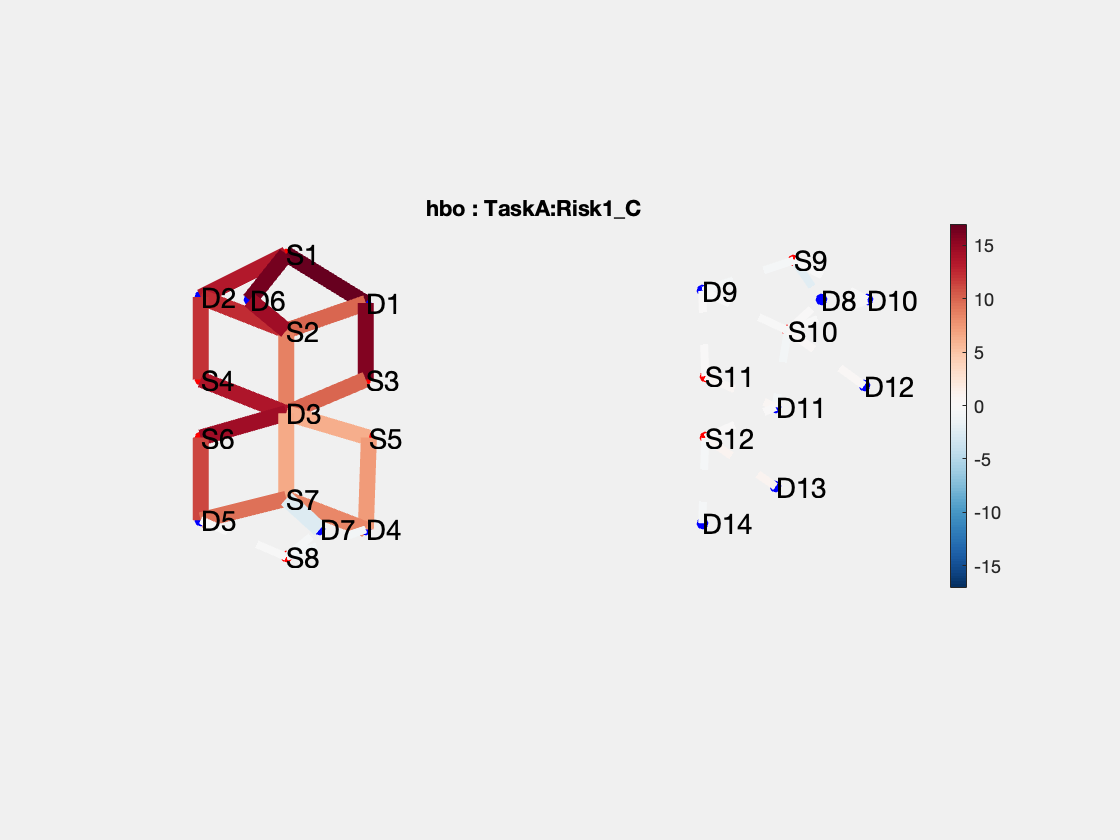

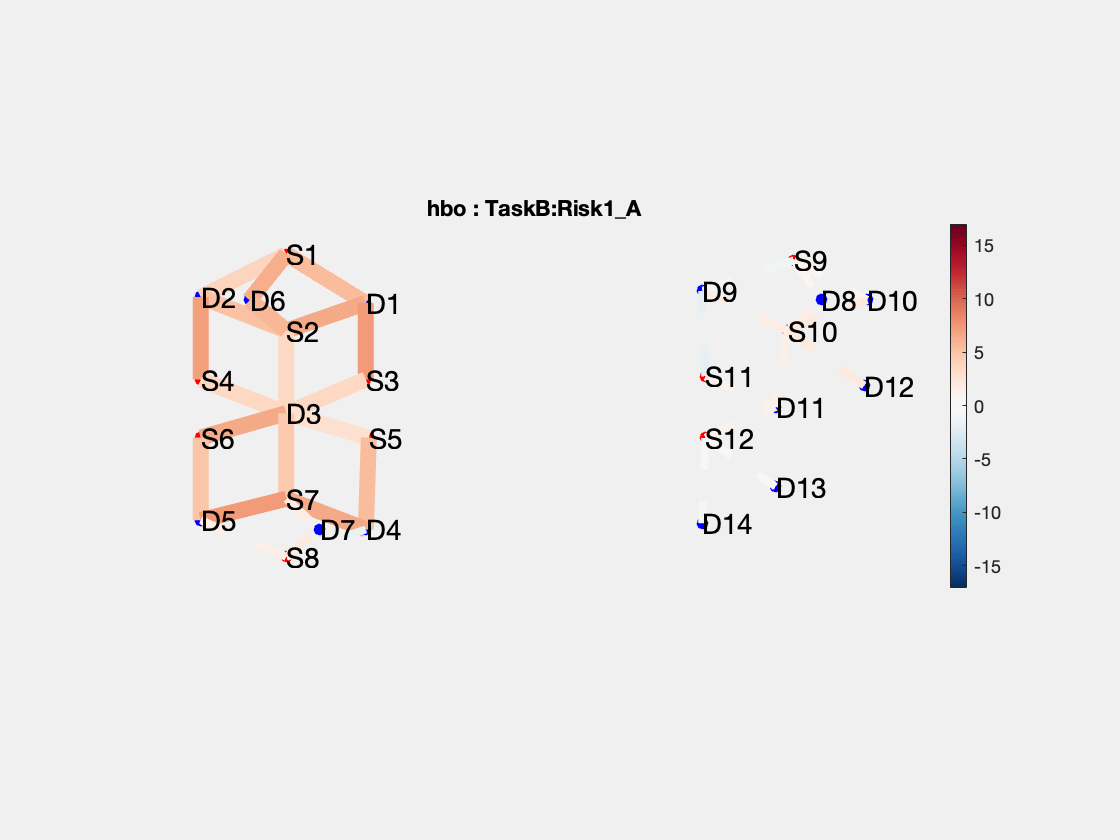

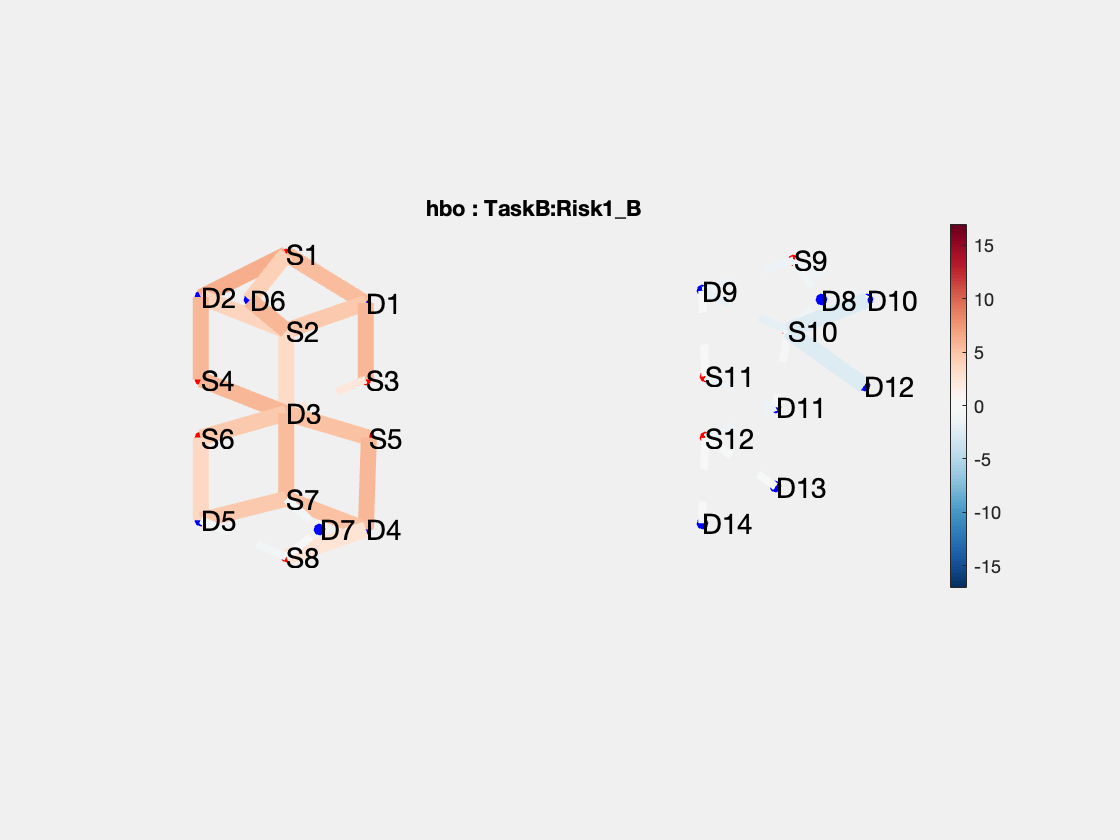

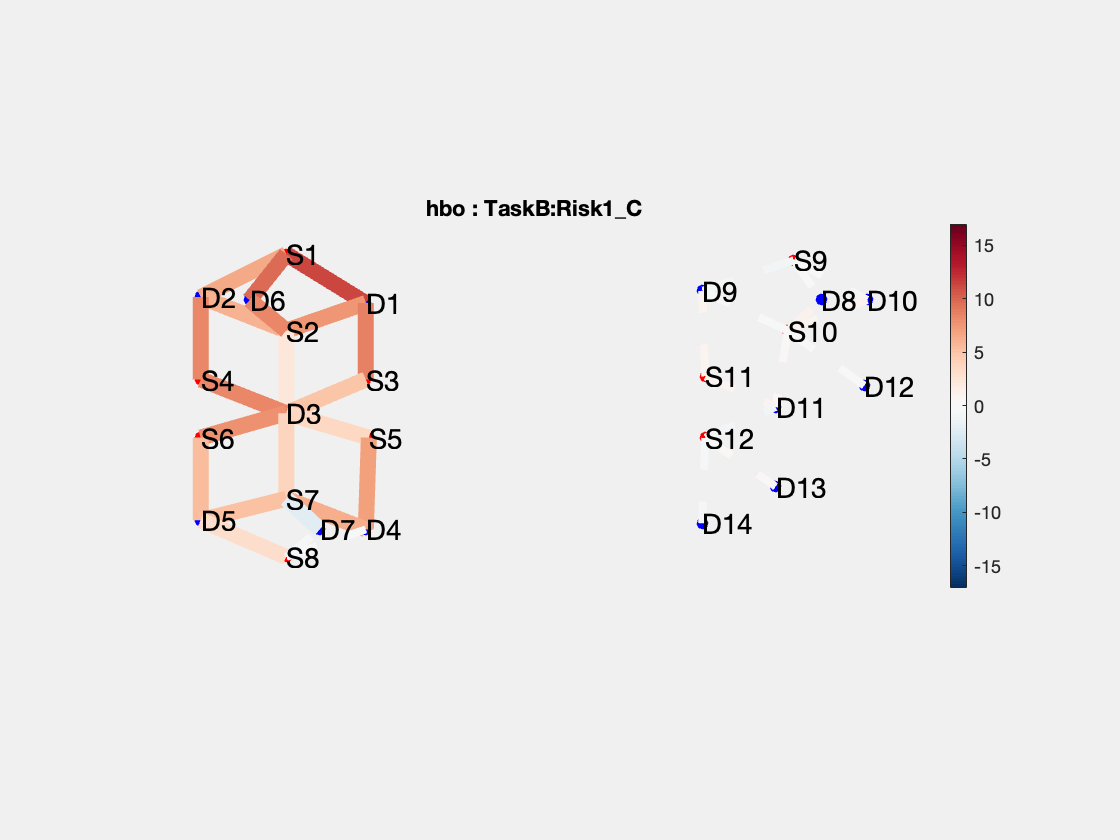

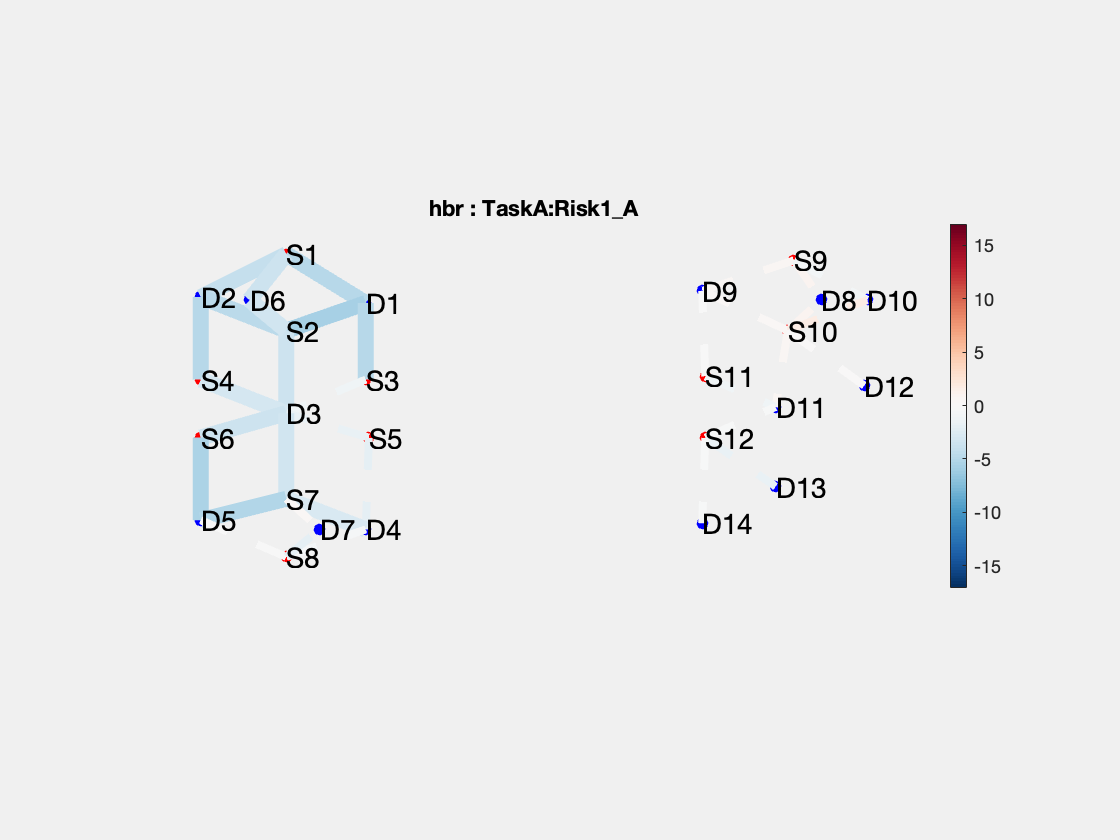

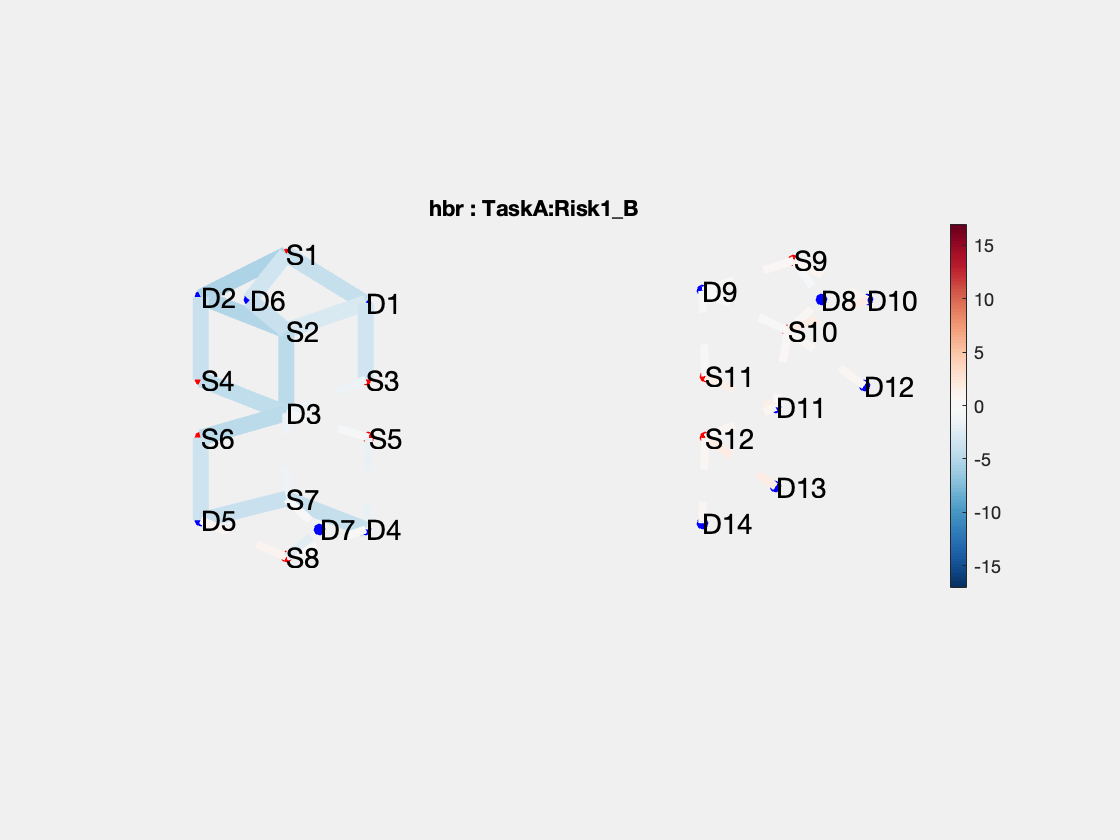

ans =   1×12 Figure array:

    Figure    Figure    Figure    Figure    Figure    Figure    Figure    Figure    Figure    Figure    Figure    Figure


Group2.draw('tstat',[],'q<0.05')

**To see the table**

tblGroup1 = Group1.table

tblGroup1 = 280×13 table
    source    detector     type           cond               model            beta          se         tstat      dfe        p             q         minDiscoverableChange    RelativePower
    ______    ________    _______    ______________    _________________    _________    _________    ________    ___    __________    __________    _____________________    _____________

      1          1        {'hbo'}    {'TaskA'     }    {1×1 LinearModel}       1.1498     0.077317      14.871    132    5.4203e-30    3.7942e-28           

tblGroup2 = Group2.table

tblGroup2 = 420×12 table
    source    detector     type            cond             beta         se        tstat     dfe        p             q         minDiscoverableChange    RelativePower
    ______    ________    _______    _________________    ________    ________    _______    ___    __________    __________    _____________________    _____________

      1          1        {'hbo'}    {'TaskA:Risk1_A'}      1.0924    0.094147     11.604    130    8.3379e-22    2.1887e-20           0.23549              0.73733   
      1          1        {'hbo'}    {'TaskB:Risk1_A'}     0.5060

#### Remove outliers

This example showing how to remove the outlier.

job = nirs.modules.RemoveOutlierSubjects;
    job.allow_partial_removal=false;
    job.cutoff=0.05;  %default 0.05
Stats2 = job.run(Stats); %This dataset remove 4 subjects

Removing 4 entries
    FileIndex    group     subject    AgeMonths     Sex     HeadSize    ADHD    Risk1
    _________    ______    _______    _________    _____    ________    ____    _____

        6        {'G1'}    {'S19'}       29        {'F'}       44        1      {'B'}
       35        {'G2'}    {'S1' }       34        {'M'}       43        4      {'A'}
       36        {'G2'}    {'S10'}       12        {'F'}       43        3      {'C'}
       40        {'G2'}    {'S2' }       29        {'F'}       44        9      {'B'}



**Contrast**

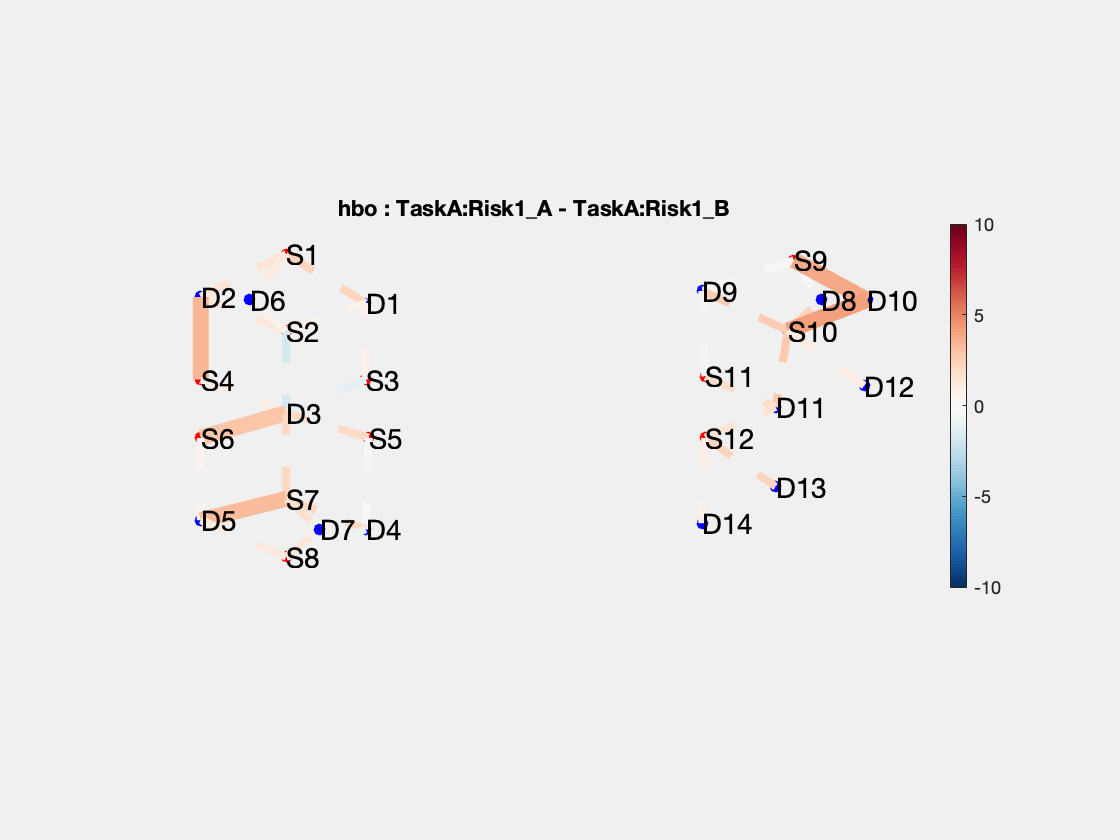

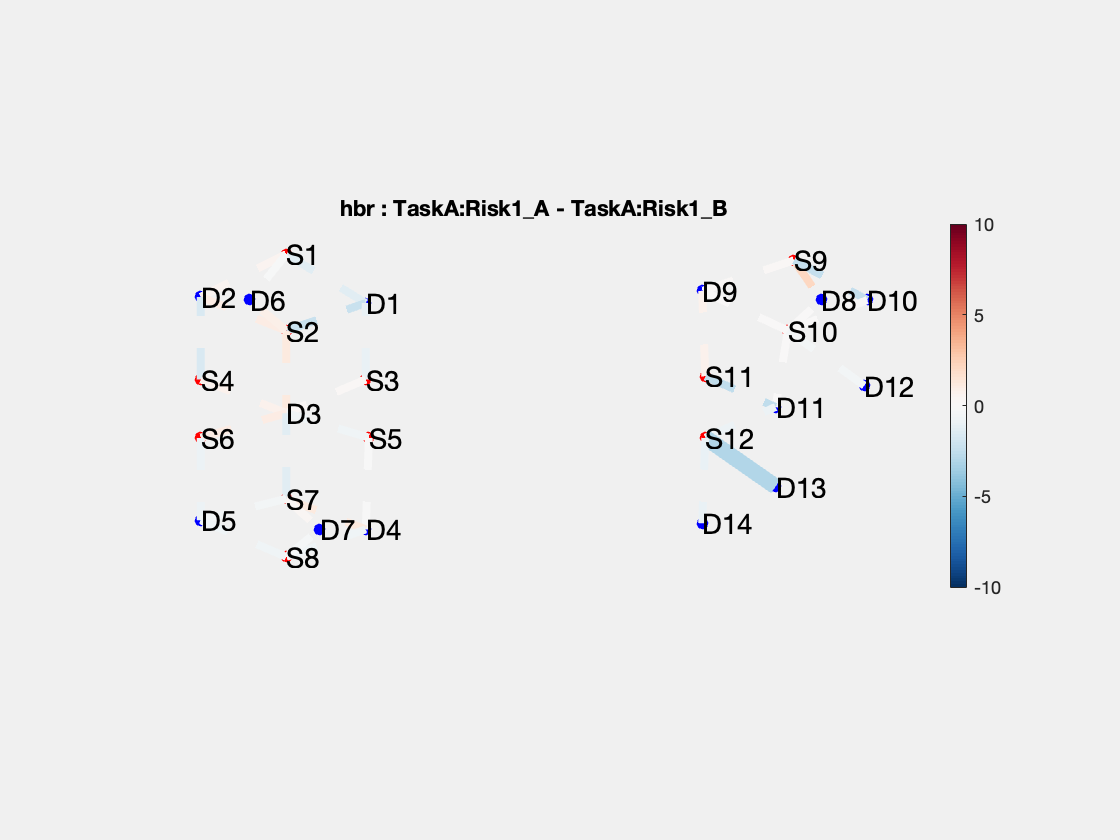

ans =   1×2 Figure array:

    Figure    Figure


Contrast1Group2 = Group2.ttest('TaskA:Risk1_A - TaskA:Risk1_B');
Contrast1Group2.draw('tstat',[-10 10], 'q<0.05')

**Scatter plot**

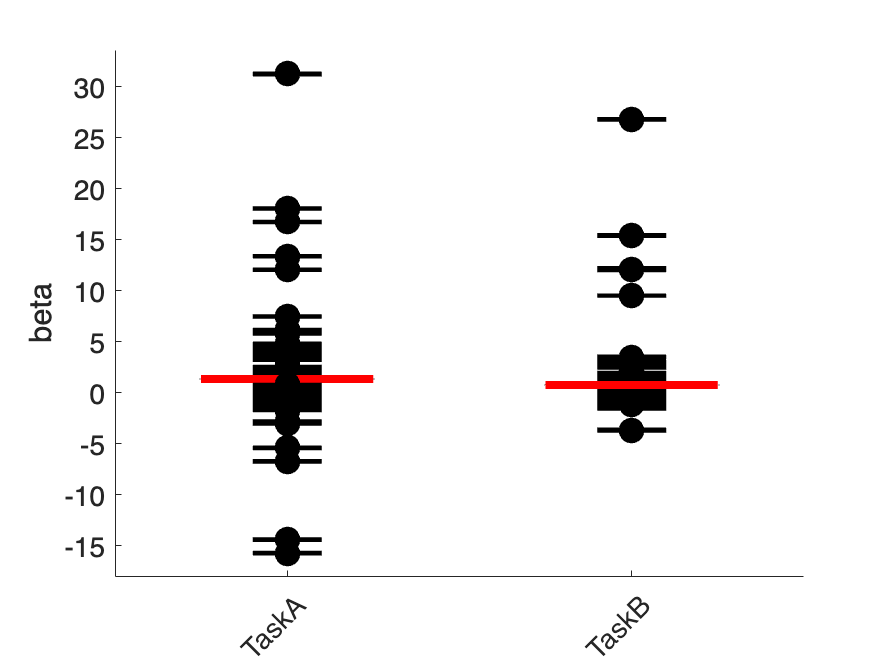

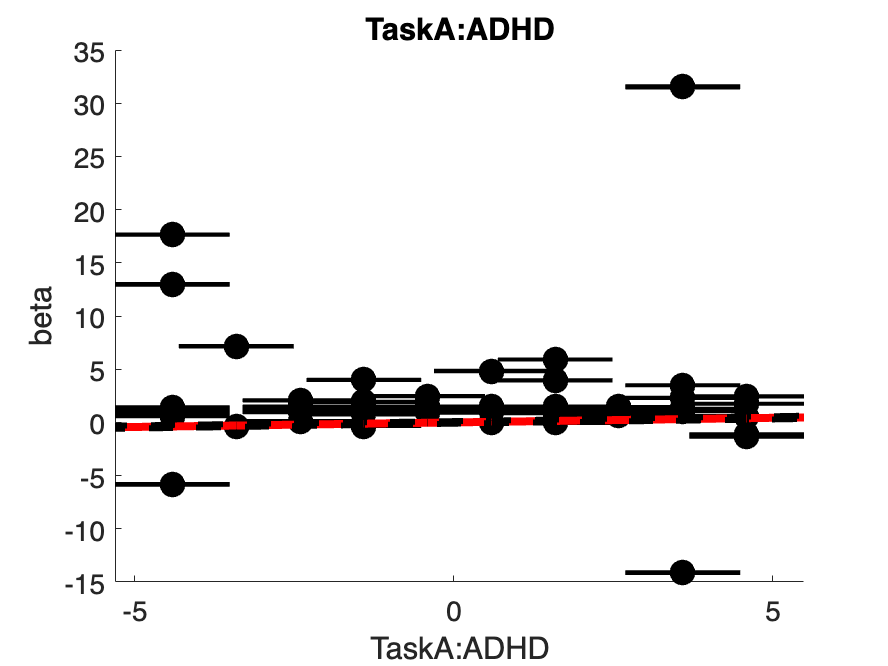

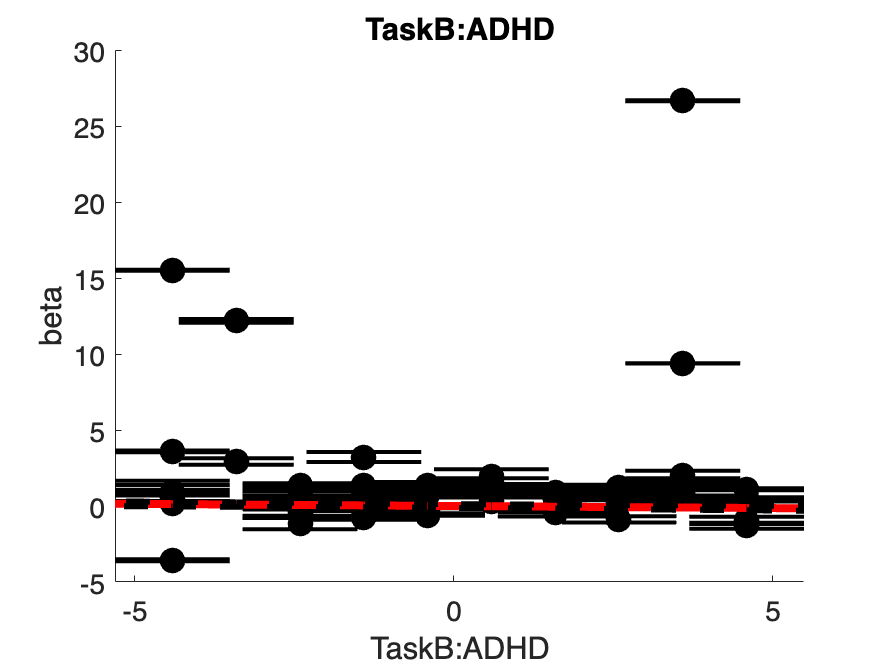

Group1.scatterplot(1, 0.95, true) %Plot channel 1 (hbo)

Group1.probe.link %See this link info

ans = 70×3 table
    source    detector     type  
    ______    ________    _______

      1          1        {'hbo'}
      1          1        {'hbr'}
      1          2        {'hbo'}
      1          2        {'hbr'}
      1          6        {'hbo'}
      1          6        {'hbr'}
      2          1        {'hbo'}
      2          1        {'hbr'}
      2          2        {'hbo'}
      2          2        {'hbr'}
      2          3        {'hbo'}
      2          3        {'hbr'}
      2          6        {'hbo'}
      2          6        {'hbr'}
      3          1        {'hbo'}
      3          1        {'hbr'}


4.2 Connectivity

4.3 Hyperscanning